# Laboratorium 1

# Przypomnienie podstaw środowiska Matlab oraz podstaw przetwarzania sygnałów.

## Zadanie rozgrzewkowe 1

Rozwiąż układ równań

x+2y+3z=1

4x+5,5y+6z=1

7x+8y+9,5z=1

syms x y z;

eqn1 = x + 2*y + 3*z == 1;
eqn2 = 4*x + 5.5*y + 6*z == 1;
eqn3 = 7*x + 8*y + 9.5*z == 1;

[A,B] = equationsToMatrix([eqn1, eqn2, eqn3], [x, y, z]);
X = linsolve(A, B);
X

$$X = \left(\begin{array}{c} -\frac{19}{29}\\ \frac{6}{29}\\ \frac{12}{29} \end{array}\right)$$

## Zadanie rozgrzewkowe 2

Sporządź wykres okręgu (równania parametryczne) dla t=[0;1)

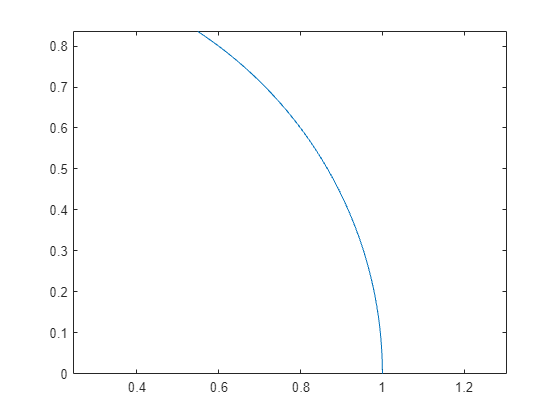

t = 0:0.01:1-0.01;
x = cos(t);
y = sin(t);


plot(x,y)
axis equal

## Zadanie rozgrzewkowe 3

Wygeneruj i przedstaw graficznie 3 okresy sygnałów. Amplituda A=+/- 1V, dla każdego wyznaczyć składową stałą i moc.

- Przebieg harmoniczny o częstotliwości f=1kHz

- Przebieg prostokątny o częstotliwości f=1kHz, wypełnieniu k=1/2 

- Przebieg piłokształtny o częstotliwości f=1kHz

- Przebieg trójkątny o częstotliwości f=1kHz

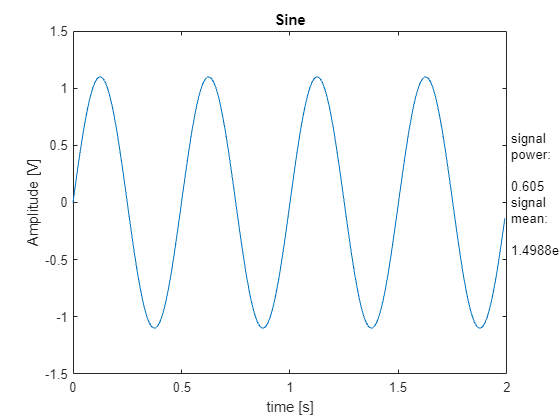

A = 1.1;
f =2;
k = 0.8;

w = 2*pi*f;
tmin = 0;
tmax = 2;
dt = 0.01;
t = tmin:dt:tmax-dt; %s

ad1 = A*sin(w*t);
power_ad1 = rms(ad1)^2;
mean_ad1 = mean(ad1);

plot(t, ad1);
title('Sine')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad1), 'signal mean: ', string(mean_ad1)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

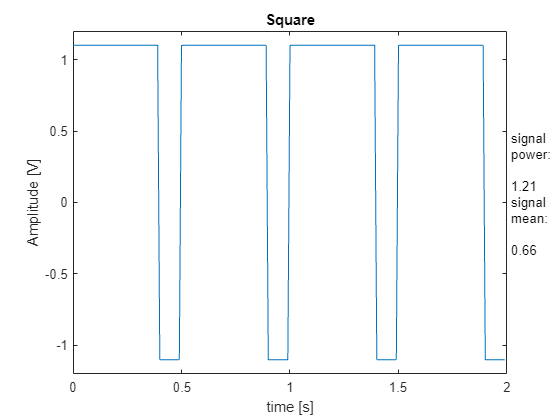

first_half = ones(1, round(1/(f*dt)*k)); second_half =  -1 * ones(1, round((1/(f*dt))*(1-k)));
ad2 = A * [first_half second_half];
for i = 0:(1/f)+1
    ad2 = cat(2,ad2,ad2);
end
power_ad2 = rms(ad2)^2;
mean_ad2 = mean(ad2);

plot(t, ad2)
ylim([-A-.1, A+0.1])
title('Square')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad2), 'signal mean: ', string(mean_ad2)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

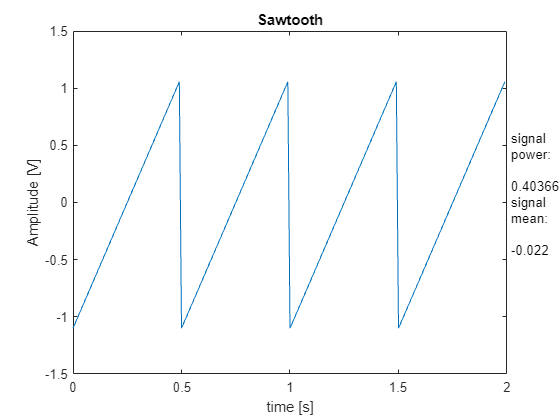

ad3 = A * sawtooth(w*t);
power_ad3 = rms(ad3)^2;
mean_ad3 = mean(ad3);

plot(t, ad3)
title('Sawtooth')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad3), 'signal mean: ', string(mean_ad3)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

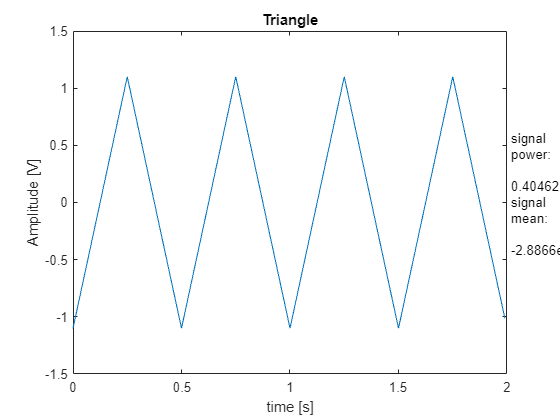


ad4 = A * sawtooth(w*t, .5);
power_ad4 = rms(ad4)^2;
mean_ad4 = mean(ad4);

plot(t, ad4)
title('Triangle')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad4), 'signal mean: ', string(mean_ad4)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

## ***Zad 1***

***Zbudować przebieg „prostokątny” o częstotliwości f=30Hz za pomocą funkcji sinusoidalnych***

- Trzech

- Pięciu

- Dziesięciu

- Stu

- Analiza przypadku (1): sygnał cyfrowy ma częstotliwość 1 MHz (2 Mbit/s), jest reprezentowany odpowiednio przez 1 i 3 oraz 1 i 3 i 5 harmoniczną, szerokość pasma, reprezentacja sygnału.

#### Opis problemu:

Każdy sygnał okresowy, spełniający warunki Dirichleta może być zbudowany za pomocą sumy sinusów różnych częstotliwości i amplitud. Sygnał prostokątny o częstotliwości f i amplitudzie A składa się z nieskończonej ilości nieparzystych harmonicznych do częstotliwości f, których amplitudy wynoszą A/n gdzie n to numer danej harmonicznej.

#### Podstawy matematyczne:

**Szereg Fouriera** – szereg pozwalający rozłożyć funkcję okresową, spełniającą warunki Dirichleta, na sumę funkcji trygonometrycznych. 

#### Symulacja:

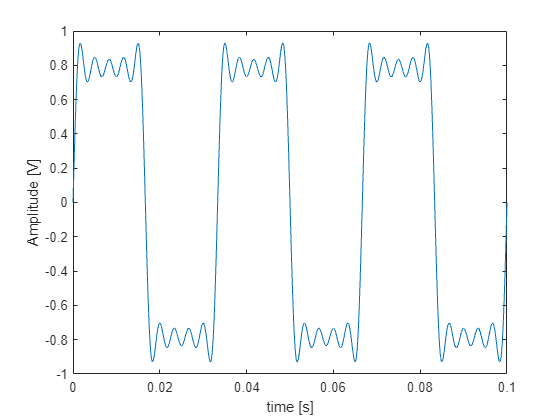

N_sines = 5;

t = 0:0.00001:3/30;
combined_sines = zeros(size(t));

for i = 1:2:N_sines*2
    combined_sines = combined_sines + (1/i) * sin(2*pi*30*i*t);
end



plot(t, combined_sines)
ylabel('Amplitude [V]')
xlabel('time [s]')

#### Obserwacje:

Wraz ze wzrostem ilości harmonicznych składających się na nasz sygnał, jego kształt jest coraz bardziej zbliżony do sygnału prostokątnego.

#### Wnioski:

Aby idealnie odwzorować przebieg prostokątny musieli byśmy złożyć go z nieskończonej ilości harmonicznych.

## **Zad 2**

Dla sygnału analogowego: $f{\left(t\right)}=5+2cos{\left(2\pi t-\frac{\pi }{2}\right)}+3\mathrm{c}\mathrm{o}\mathrm{s}\left(4\pi t\right)$

- Dobierz  częstotliwość próbkowania fs sygnału f(t). Zaproponuj czas obserwacji - konsekwencje. Wyznacz DFT sygnału (wskazy). 

- Zmieniając liczbę bitów przetwornika AC (np. bit = 1, 3, 4, 8, 10), zbadać: jak zmienia się obraz próbkowanego sygnału, poziom (rząd wielkości) błędów kwantyzacji, porównać maksymalny błąd kwantyzacji z połową przedziału kwantowania, jakie zniekształcenia się pojawiają (wyższe harmoniczne sygnału), dla bit=1, 2, 4, 8 wyznacz współczynnik zawartości harmonicznych. Określ odstęp i szum kwantyzacji.

#### Opis problemu:

Jak należy dobierać parametry przetwornika analogowo cyfrowego takie jak czas obserwacji, częstotliwość próbkowania oraz ilość bitów adc aby otrzymać poprawne cyfrowe odwzorowanie próbkowanego sygnału? Jaki wpływ zmiany tych parametrów mają na widmo dft sygnału oraz próbkowany sygnał?

#### Podstawy matematyczne:

Twierdzenie o próbkowaniu - Jeśli sygnał ciągły nie ma składowych widma o częstotliwości równej lub większej niż B, może on zostać jednoznacznie odtworzony z ciągu jego próbek tworzących sygnał dyskretny, o ile próbki te zostały pobrane z częstotliwością co najmniej 2B.

Warunki transformaty fouriera - funkcja musi spełniać warunki dirichleta tzn dziedzinę f(x) można rozłożyć na skończoną sumę przedziałów, w których f(x) jest monotoniczna i ciągła oraz w każdym punkcie nieciągłości x0 , granice jednostronne limx→x − 0 f(x) i limx→x + 0 f(x) są skończone. Funkcja musi być całkowalna i ciągła w całym przedziale.

#### Symulacje:

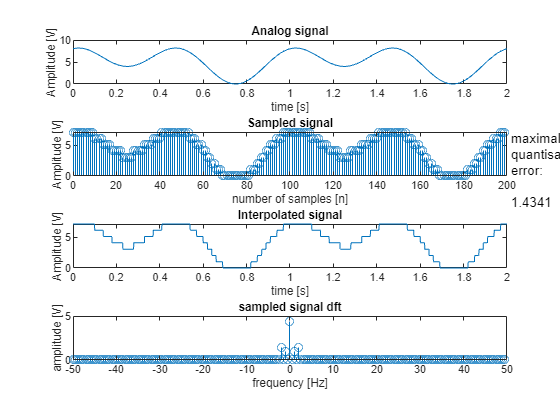

observation_time = 2; %observation time [seconds] %N
sampling_frequency = 100; % sampling frequency [Hz]
ADC_bits = 3; % number of adc bits


fs = sampling_frequency;
bits = ADC_bits;

t = 0:0.001:observation_time;
signal = 5 + 2*cos(2*pi*t-pi/2) + 3*cos(4*pi*t);

Q = (max(signal)/2^bits); % adc qwant
Ts = 1/fs; %sampling period
N = observation_time/Ts; %number of samples

n = 0:N-1;

sampled_signal = floor((5 + 2*cos(2*pi*(n*Ts)-pi/2) + 3*cos(4*pi*n*Ts)) / Q) * Q;

interpolated_signal = imresize(sampled_signal, [1 length(t)], 'nearest');
q_error = max(signal - interpolated_signal);

signal_fft = fft(sampled_signal);
frequency_vector = (fs/length(n))*(-length(n)/2:(length(n)/2)-1);

subplot(4,1,1)
plot(t, signal)
title('Analog signal')
ylabel('Amplitude [V]')
xlabel('time [s]')

subplot(4,1,2)
stem(n, sampled_signal)
xlim([0, N])
title('Sampled signal')
ylabel('Amplitude [V]')
xlabel('number of samples [n]')
txt = ['maximal quantisation error: ', string(q_error)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

subplot(4,1,3)
plot(t, interpolated_signal)
title('Interpolated signal')
ylabel('Amplitude [V]')
xlabel('time [s]')

subplot(4,1,4)
stem(frequency_vector, abs(fftshift(signal_fft))/length(n))
xlim([-fs/2, fs/2])
title('sampled signal dft')
xlabel('frequency [Hz]')
ylabel('amplitude [V]')

#### Obserwacje:

Sygnał może być odwzorowany dopiero gdy częstotliwość próbkowania wynosi 4Hz, tzn 2xczęstotliwość najwyższej harmonicznej sygnału. Dalsze zwiększanie częstotliwości próbkowania pozwala na coraz dokładniejsze odwzorowanie.

Taki sam efekt ma zwiększanie ilości bitów przetwornika. Im mniej bitów przetwornika tym mniej poszczególnych poziomów sygnały jesteśmy w stanie zarejestrować co powoduje zwiększenie błędu kwantyzacji.

Stosując czas obserwacji inny niż wielokrotność 1Hz w widmie częstotliwościowym pojawiają się harmoniczne wynikające z nieciągłości powstałych na granicach sygnału.

#### Wnioski:

Aby dokładnie odwzorować sygnał należy stosować częstotliwość próbkowania 10x większą od najwyższej częstotliwości składowej sygnału.

Czas obserwacji musi wynosić wielokrotność okresu składowej o najniższej częstotliwości, w przeciwnym wypadku na granicach sygnału powstaną nieciągłości które pojawią się w widmie częstotliwościowym.